# 数字信号处理课程设计——插值

clc;clear sound;close all;

### 读取音频

Fs=44100;
T_start=79;
T_end=80;
interval=T_end-T_start;
narr=50;
music=audioread("The Truth That You Leave.mp3",round([T_start*Fs,T_end*Fs]));
music=music(:,1)';
% music=ones(1,300);
% audioinfo("The Truth That You Leave.mp3")

### 使用resample函数插值

% disp('使用resample函数插值用时')
tic
y1=Resample_I(music,narr);
toc

历时 0.065052 秒。


### 直接抽取进行插值

% disp('直接插值时')
tic
y2=DirectInterpolation(music,narr);
toc

历时 0.026891 秒。


### 插值后直接卷积

% disp('插值后直接卷积用时')
tic
y3=Convolution_I(music,narr);
toc

历时 0.073445 秒。


### 多相滤波插值

% disp('多相滤波插值用时')
tic
y4=PolyphaseFilter_I(music,narr);
toc

历时 0.100597 秒。


%关于为什么多相滤波插值会更慢，是因为程序中使用的结构稳定消耗运行最终结果的长度的内存

### 观察频谱

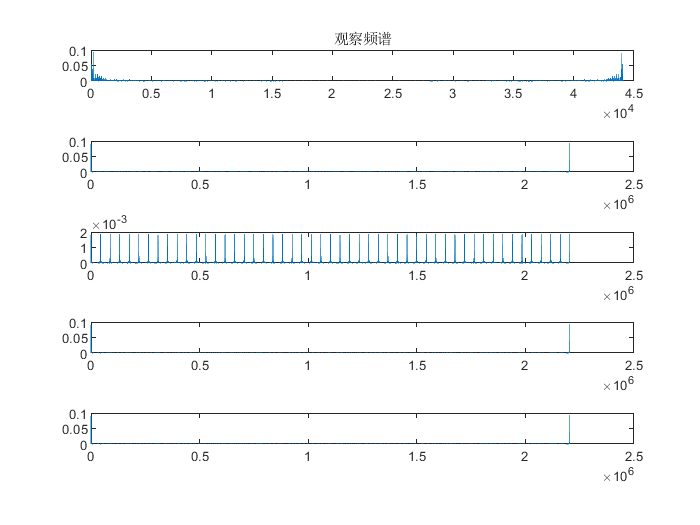

t=1:length(y1);
w=t.*Fs/length(y1)*narr;
t=t./Fs/narr;
figure(1)
subplot(511)
plot((1:length(music)).*Fs./length(music),abs(fft(music))/length(music));
title('观察频谱')
subplot(512)
plot(w,abs(fft(y1))/length(y1));
subplot(513)
plot(w,abs(fft(y2))/length(y2));
subplot(514)
plot(w,abs(fft(y3))/length(y3));
subplot(515)
plot(w,abs(fft(y4))/length(y4));


% figure(1)
% subplot(511)
% plot((1:length(music)).*Fs./length(music),fftshift(abs(fft(music)))/length(music));
% title('观察频谱')
% subplot(512)
% plot(t,fftshift(abs(fft(y1)))/length(y1));
% subplot(513)
% plot(t,fftshift(abs(fft(y2)))/length(y2));
% subplot(514)
% plot(t,fftshift(abs(fft(y3)))/length(y3));
% subplot(515)
% plot(t,fftshift(abs(fft(y4)))/length(y4));

### 观察时域波形

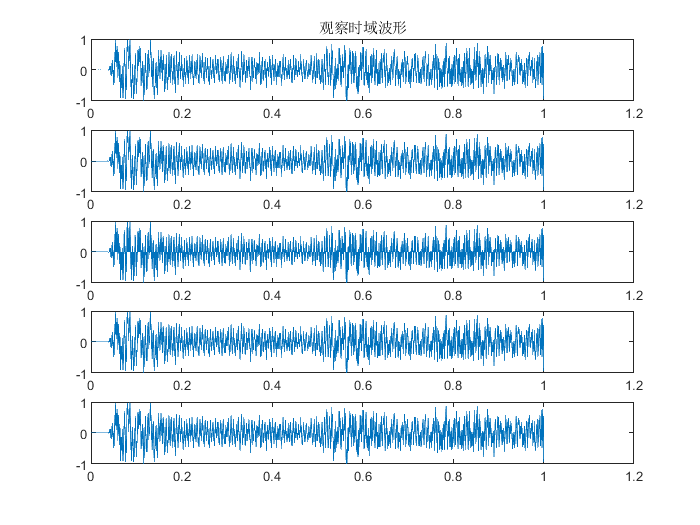

figure(2)
subplot(511)
plot((1:length(music))/Fs,music);
title('观察时域波形')
subplot(512)
plot(t,y1);
subplot(513)
plot(t,y2);
subplot(514)
plot(t,y3);
subplot(515)
plot(t,y4);

### 播放音频

% sound(music,Fs)
% pause(interval)
% sound(y1,Fs/narr)
% pause(interval)
% sound(y2,Fs/narr)
% pause(interval)
% sound(y3,Fs/narr)
% pause(interval)
% sound(y4,Fs/narr)
% pause(interval)

### 计算信噪比

disp('计算信噪比：')

计算信噪比：


s=sum(y1.^2);
sig21=sum((y2-y1).^2);SNR2=10*log10(s/sig21)

SNR2 = 0.0878

sig31=sum((y3-y1).^2);SNR3=10*log10(s/sig31)

SNR3 = 48.7752

sig41=sum((y4-y1).^2);SNR4=10*log10(s/sig41)

SNR4 = 48.7752

disp(['SNR3-SNR2=',num2str(SNR3-SNR2)])

SNR3-SNR2=48.6874


disp(['|SNR3-SNR4|=',num2str(abs(SNR3-SNR4))])

|SNR3-SNR4|=0


### 分数倍速率转换

% I=19;
% D=37;
% after_transf=transfer(music,I,D);
% 
% figure(3)
% subplot(211)
% plot(music)
% title('时域波形对比')
% subplot(212)
% plot(after_transf)
% 
% figure(4)
% subplot(211)
% plot((1:length(music)).*Fs./length(music),abs(fft(music))/length(music));
% title('频谱对比')
% subplot(212)
% plot((1:length(after_transf)).*Fs./length(after_transf),abs(fft(after_transf))/length(after_transf))
% 
% sound(music,Fs)
% pause(interval)
% sound(after_transf,Fs*I/D)
% pause(interval)
